%set time range
t = 0:0.02:10

t =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


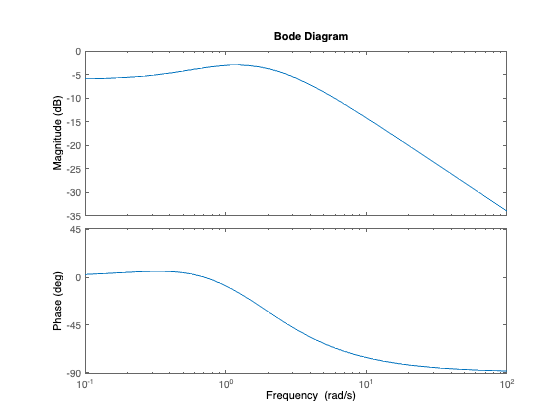


%go into s-plane alphanumeric mode
s = tf('s');

%Set up transfer Function
H = (2*s + 1) / (s^2 +3*s + 2);

%plot the Bode Plot and Pole Diagram
bode(H);

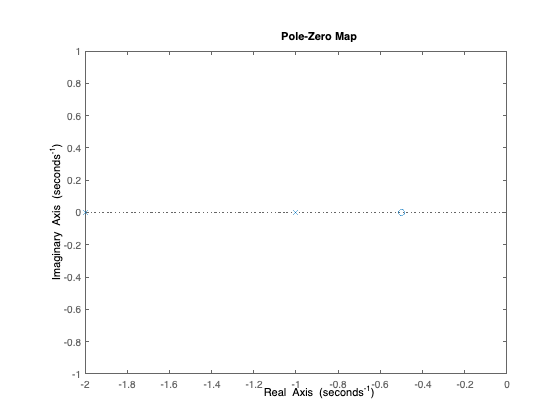

pzplot(H);

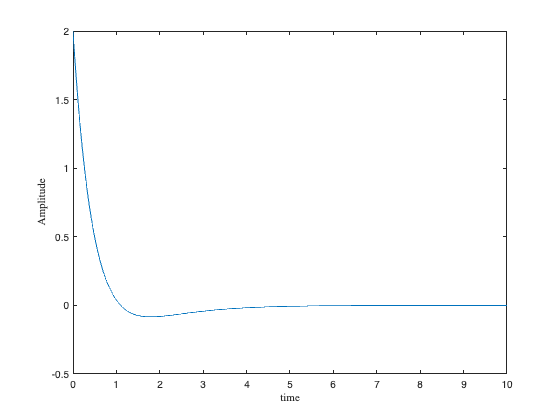


%plot the time domain (inverse Laplace)
y = impulse(H,t);
plot(t,y)
xlabel ('time')
ylabel ('Amplitude')